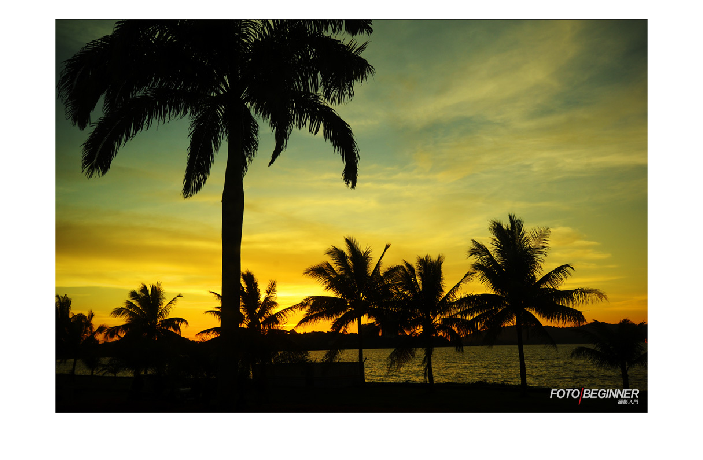

%help sort
clear all;
clf;
sky=imread('Q1\sky.jpg');
imshow(sky);

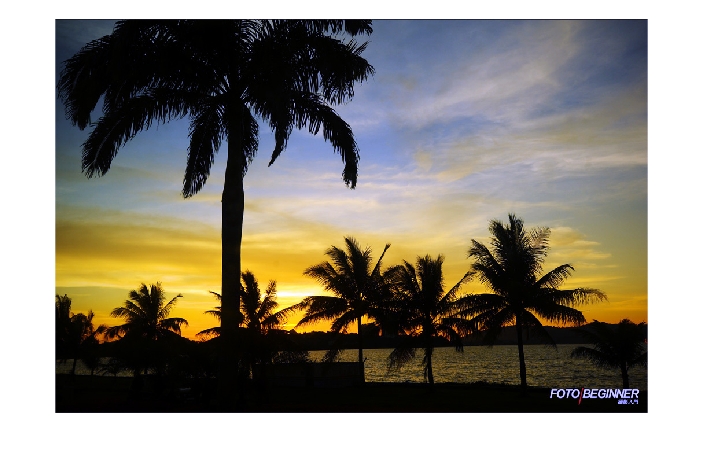

fr=sky(:,:,1);
fg=sky(:,:,2);
fb=sky(:,:,3);
[m,n]=size(fr);
rmax=max(fr(:));gmax=max(fg(:));bmax=max(fb(:));
srgb=min([rmax,gmax,bmax]);
nr=sum(sum(fr>srgb));ng=sum(sum(fg>srgb));nb=sum(sum(fb>srgb));
nmax=max([nr,ng,nb]);
r=sort(fr(:),'descend');tr=r(nmax);
g=sort(fg(:),'descend');tg=g(nmax);
b=sort(fb(:),'descend');tb=b(nmax);
kr=srgb/tr;kg=srgb/tg;kb=srgb/tb;
gr=kr*fr;gg=kg*fg;gb=kb*fb;
colorbalance=cat(3,gr,gg,gb);
imshow(colorbalance);